## Assignment 3

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

Tristan de le Cruz Hachiles (405541)

% Class Objects
IT = InterplanetaryTransfers;
OP = OrbitPropagation;
warning('off','all')

## Task 1: Solving Lambert's Problem

Below we verify the correctness of the Lambert solver using the secant method with the given test-cases which match the results, for both cases.

### Test-Case A: Planetary Transfer Earth-Venus

% Constants Earth-Venus transfer
delta_theta_A  = deg2rad(75);           % rad
dt_A           = 180;                   % days
mu_A           = 398600.440;            % km³/s²
mu_converted_A = 0.00029591220828559;   % AU³/days²
rr_1_A         = [1 0 0]';              % AU
rr_2_A         = [0.187, 0.698, 0]';    % AU
factors_A      = [1, 2];                % [1]
max_iters      = 20;                    % [1]
tolerance_A    = 1E-8;                  % [1]

% Solve
[vv_1_A, vv_2_A, a_A] = IT.solve_lamberts_problem_secant(rr_1_A, rr_2_A, ... 
                                                         delta_theta_A, ...
                                                         dt_A, ...
                                                         mu_converted_A, ...
                                                         factors_A, ...
                                                         max_iters, ...
                                                         tolerance_A);
% Conversion factor from AU to km
AU_km   = 149597870.7;       % Km
day_s   = 1 * 24 * 60 * 60;  % s
fac_A   = AU_km / day_s;     % Km / s 

% Results of the Earth-Venus Transfer
disp("Velocities of Earth-Venus Transfers")

Velocities of Earth-Venus Transfers


vv_1_A = vv_1_A * fac_A     % Km / s

vv_1_A =    18.8368
   17.4054
         0


vv_2_A = vv_2_A * fac_A     % Km / s

vv_2_A =   -30.3940
  -20.3722
         0


### Test-Case B: Planetary Transfer Earth-Mars

% Inputs Case 2

delta_theta_B   = deg2rad(143.451);                                     % rad
dt_B            = 203 / 365.24219;                                      % Tropical years
mu_converted_B  = 4*pi^2;                                               % AU³/year²
rr_1_B          = [0.605774717586, -0.80374565571, 0.00010684714]';     % AU
rr_2_B          = [-0.01300489410, 1.575580535344, 0.033161980867]';    % AU
factors_B       = [1, 1.001];                                           % [1]
tolerance_B     = 1E-10;                                                % [1]

[vv_1_B, vv_2_B, a_B] = IT.solve_lamberts_problem_secant(rr_1_B, rr_2_B, ...
                                                        delta_theta_A, dt_B, ...
                                                        mu_converted_B, ...
                                                        factors_B, max_iters, tolerance_B);

% Results of the Earth-Mars Transfer
disp("Velocities of Earth-Mars Transfer:")

Velocities of Earth-Mars Transfer:


vv_1_B, vv_2_B % AU / year

vv_1_B =     1.4374
    3.3523
    0.1122


vv_2_B =    -2.0401
    2.1739
   -0.0117


## Task 2: Generating Porkchop Plots

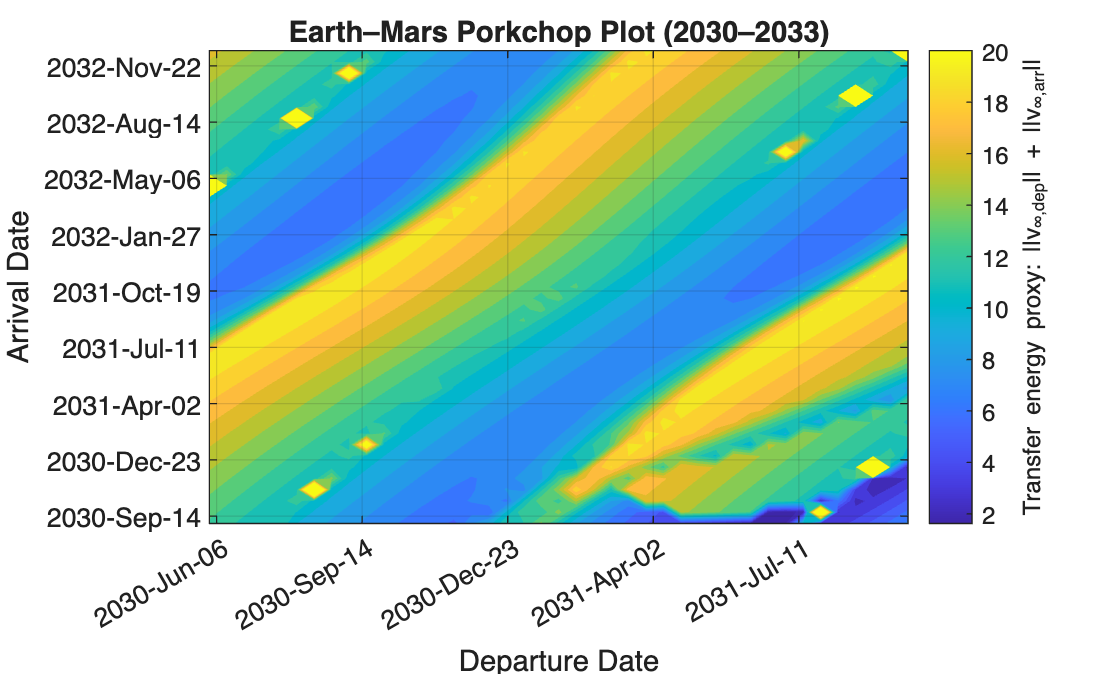

mu_converted = 39.4784176; %AU³/year²

% parse data files
[earth_data] = IT.parse_horizon_file('data/earth_data.txt', 'year');
[mars_data] = IT.parse_horizon_file('data/mars_data.txt', 'year');

% Create struct of lambet solver parameters
lsp.mu = mu_converted;
lsp.factors = [1, 2];
lsp.max_iterations = 20;
lsp.tolerance = 1E-8;

IT.create_porkchop_plot(lsp, earth_data, mars_data);

The porkchop plot shows the energetic feasibility of Earth–Mars transfers as a function of **departure date from Earth** and **arrival date at Mars**.

For each departure–arrival date combination, Lambert’s problem is solved using heliocentric ephemerides from the JPL Horizons system.

The color scale represents the transfer energy derived from the hyperbolic excess velocity obtained from the Lambert solution, while the diagonal structures indicate regions of approximately constant **time of flight**.

Low-energy regions correspond to favorable launch windows with reduced transfer energy requirements.

The plot covers departure dates from **June 2030 to September 2031** and arrival dates from **September 2030 to January 2033**, allowing suitable Earth–Mars transfer opportunities to be identified within this timeframe.

The Code is Explained in InterplanetaryTransfers.m

## Task 3: Patched-Conics Trajectory

% Test: Create porkchop plot

% parse data files
[earth_data] = IT.parse_horizon_file('westphal/data/earth_data.txt', 'year'); % AU

Error using InterplanetaryTransfers.parse_horizon_file (line 73)
Cannot open file: westphal/data/earth_data.txt

[mars_data] = IT.parse_horizon_file('westphal/data/mars_data.txt', 'year');   % AU

% Create all orbits for an earth mars transfer
mu_sun_converted    = 39.4784176; %AU³/year²
mu_earth_converted  = 1.1857 * 10^(-4);  %AU³/year²
perigee_height      = 1.34 * 10^-6; %AU
Re                  = 4.26 * 10^-5; %AU

% Create struct of lambet solver parameters
lsp.mu              = mu_sun_converted;
lsp.factors         = [1, 2];
lsp.max_iterations  = 20;
lsp.tolerance       = 1E-6;

% Return minimum departure velocity
[vv_inf_dep_min, date_dep, ~, ~] = IT.minimum_vinf_transfers(lsp, earth_data, mars_data)
% Return minimum arrival velocity
[~,~, vv_inf_arr_min, date_arr] = IT.minimum_vinf_transfers(lsp, earth_data, mars_data)


## TODO: